% Parameters for the dataset
num_samples = 500; % Total number of samples
num_features = 2;  % Number of features
class_sep = 1.5;   % Degree of separability
rng(42);           % Set seed for reproducibility

% Generate random data for two classes
X_class1 = randn(num_samples/2, num_features) - class_sep; % Shift class 1
X_class2 = randn(num_samples/2, num_features) + class_sep; % Shift class 2

% Combine the two classes
X = [X_class1; X_class2];
y = [ones(num_samples/2, 1); -ones(num_samples/2, 1)]; % Labels (1 for class 1, -1 for class 2)

% Combine features and labels into one matrix
data = [X, y]

data =    -2.0382   -2.3730    1.0000
   -0.6328   -1.3454    1.0000
   -0.5240    0.5043    1.0000
   -1.1626   -0.4491    1.0000
   -2.4961   -1.4055    1.0000
   -2.0232   -2.3212    1.0000
   -2.7974   -1.0736    1.0000
   -0.5826   -0.2321    1.0000
   -1.3234   -2.2997    1.0000
   -0.7448   -1.4566    1.0000



% Write the data to a CSV file
csv_filename = 'synthetic_dataset.csv';
header = {'Feature1', 'Feature2', 'Label'};
fid = fopen(csv_filename, 'w');
fprintf(fid, '%s,%s,%s\n', header{:}); % Write header
fclose(fid);

% Append data
dlmwrite(csv_filename, data, '-append');

disp(['Dataset written to ', csv_filename]);

Dataset written to synthetic_dataset.csv


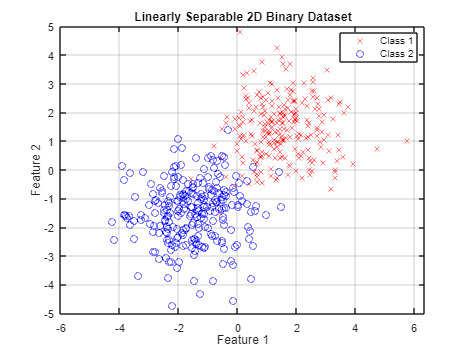


% Visualize the dataset
figure;
gscatter(X(:,1), X(:,2), y, 'rb', 'xo');
xlabel('Feature 1');
ylabel('Feature 2');
title('Linearly Separable 2D Binary Dataset');
legend('Class 1', 'Class 2');
grid on;